load pagerank_adj.mat
A = zeros(size(J));
for i = 1:length(J)
    A(:,i) = J(:,i)/sum(J(:,i));
end

x1(:,1) = ones(length(A), 1);
k = 1; 
x1(:,1) = x1(:,1)/norm(x1(:,1));
for i = 1:10
   y(:,k) = A*x1(:,k);
   x1(:,k+1) = y(:,k)/norm(y(:,k));
   lambda(k) = x1(:,k+1)' * A * x1(:,k+1);
   e1(k) = norm(A*x1(:,k)-x1(:,k));
   k = k + 1;
end 
[maxis,maxidx] = maxk(x1(:,end),5)

maxis =     0.4394
    0.3296
    0.3073
    0.2996
    0.2751


maxidx =      2
    35
    36
    58
    49


[minis,minidx] = mink(x1(:,end),5)

minis =      0
     0
     0
     0
     0


minidx =      1
     3
     4
     5
    10


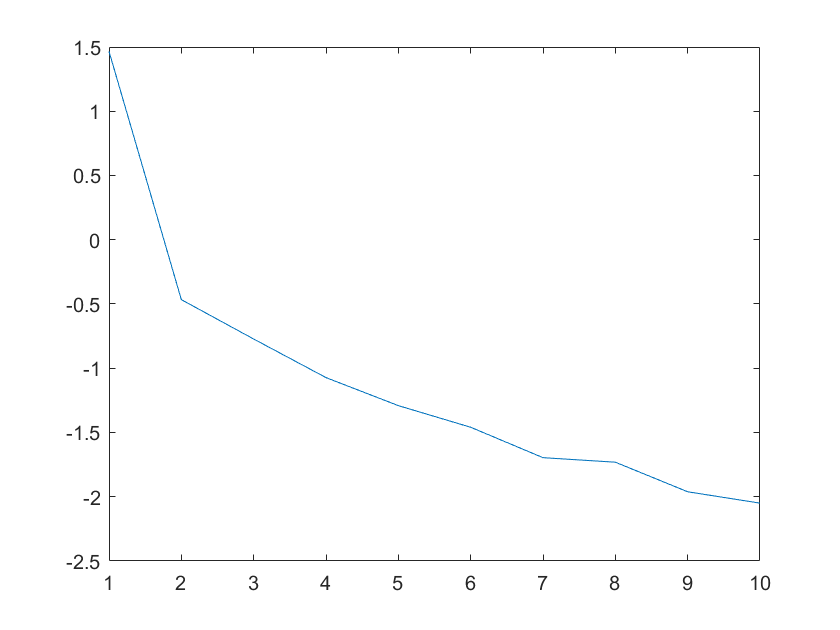

figure;
plot(log(e1))

x2(:,1) = ones(length(A), 1);
k = 1; 
sigma = 0.99;
x2(:,1) = x2(:,1)/norm(x2(:,1));
for i=1:10
   y(:,k) = (A-sigma*eye(length(A))) \ x2(:,k);
   x2(:,k+1) = y(:,k)/norm(y(:,k));
   lambda(k) = x2(:,k+1)' * A * x2(:,k+1);
   e2(k) = norm(A*x2(:,k)-x2(:,k));
   k = k + 1;
end
[maxis,maxidx] = maxk(x2(:,end),5)

maxis =     0.3711
    0.3184
    0.2975
    0.2904
    0.2637


maxidx =      2
    35
    36
    58
    49


[minis,minidx] = mink(x2(:,end),5)

minis =    -0.3196
   -0.1602
   -0.1602
   -0.1200
   -0.0917


minidx =    424
   987
   986
   985
   930


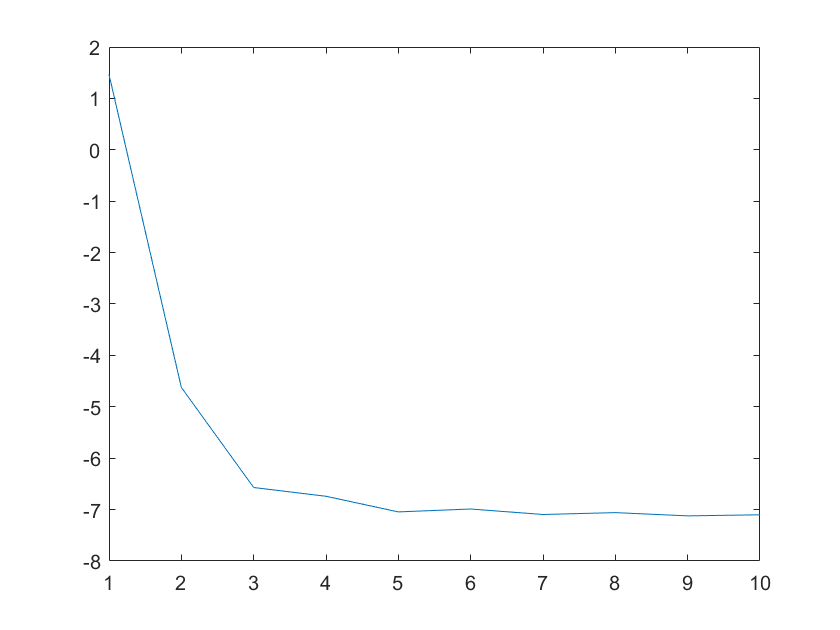

figure;
plot(log(e2))

x3(:,1) = ones(length(A), 1);
k = 1; 
x3(:,1) = x3(:,1)/norm(x3(:,1));
for i=1:10
   if i==1 || i==2
       sigma = 0.99;
   else
       sigma = (x3(:,k)' * A * x3(:,k))/(x3(:,k)' * x3(:,k));
   end
   y(:,k) = (A-sigma*eye(length(A))) \ x3(:,k);
   x3(:,k+1) = y(:,k)/norm(y(:,k));
   e3(k) = norm(A*x3(:,k)-x3(:,k));
   k = k + 1;
end

[maxis,maxidx] = maxk(x3(:,end),5)

maxis =     0.0432
    0.0432
    0.0432
    0.0432
    0.0432


maxidx =    303
   731
   732
   733
   735


[minis,minidx] = mink(x3(:,end),5)

minis =    -0.4479
   -0.2648
   -0.2593
   -0.2240
   -0.2240


minidx =          424
        2459
         930
         986
         987


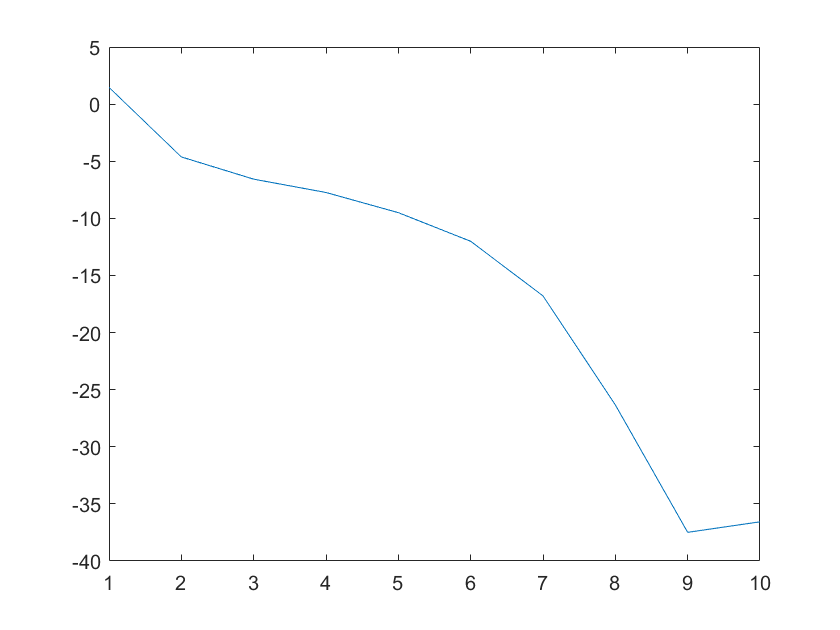

figure;
plot(log(e3))

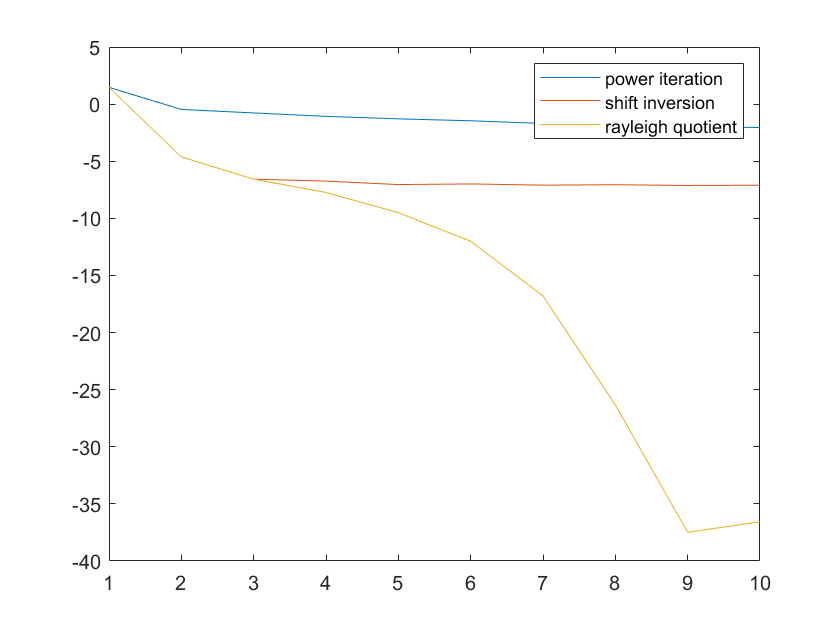

figure;
plot(log(e1))
hold on
plot(log(e2))
hold on;
plot(log(e3))
legend('power iteration', 'shift inversion', 'rayleigh quotient')